clear all;
close all;
clc;

addpath("SensorFusion");
addpath("funzioni");
run("estraz_dati_sens_fus.m");

T_synced = 8826×15 table
    Tempo [s]    X_ARUCO [m]    Y_ARUCO [m]    Z_ARUCO [m]    DegX_ARUCO [deg]    DegY_ARUCO [deg]    DegZ_ARUCO [deg]    Left_ENC [tic]    Right_ENC [tic]    OmegaX_IMU_Fixed [deg/s]    OmegaY_IMU_Fixed [deg/s]    OmegaZ_IMU_Fixed [deg/s]    AccX_IMU_Fixed [g]    AccY_IMU_Fixed [g]    AccZ_IMU_Fixed [g]
    _________    ___________    ___________    ___________    ________________    ________________    ________________    ______________    _______________    ________________________    ________________________    ____

### Encoders Data extraction

MOTION_START = 125;

NTic_R = table2array(T_synced(1:end,"Right_ENC [tic]"));
NTic_L = table2array(T_synced(1:end,"Left_ENC [tic]"));

%Tic incremento at each step steps
NTic_R = diff(NTic_R);
NTic_L = diff(NTic_L);


### Data 

b= 0.8291; 
Rr = 0.0873;
Rl = 0.0857;
Enc_res = 4096;

K_param = [b Rr Rl];


## Covariance Computation

References: 

- [https://github.com/Sollimann/CleanIt/blob/main/autonomy/src/slam/README.md](https://github.com/Sollimann/CleanIt/blob/main/autonomy/src/slam/README.md)

- [https://www.youtube.com/watch?v=ubg_AAM7Zd8](https://www.youtube.com/watch?v=ubg_AAM7Zd8)

To compute the covariance matrix of the odometry model one has to use the followng formula:


$$\Sigma_{X_{k+1}} = \nabla f_{X} \cdot \Sigma__{X_{k}} \cdot \nabla f_{X}^T + \nabla f_{u} \cdot \Sigma_{u_{k}} \cdot \nabla f_{u}^T$$


Where: 

- $\Sigma_{X_{k}}$ is the covariance matrix of the position at the previous step

- $\Sigma_{u_{k}}  = \Sigma_{u}$ is the covariance of the control inputs

- $\nabla f_{X}$ is the Jacobian of the odometry model wrt the state X = [x, y, theta]

- $\nabla f_{u}$ is the Jacobian of the odometry model wrt the control inputs u = [Ntic_R, Ntic_L]

This formula comes from the propagatio nof uncertainties i nthe non linear case (see [https://en.wikipedia.org/wiki/Propagation_of_uncertainty).](https://en.wikipedia.org/wiki/Propagation_of_uncertainty).)

More details are present in the first two links.

Now the two jacobianz are reported:

[Fx_sym, Fu_sym] = print_syst_V2();

% Jacobian of the odometry model wrt the state X = [x, y, theta]
Fx_sym

$$Fx\_sym = \left(\begin{array}{ccc} 1 & 0 & -\frac{\pi \,\sin\left(\theta -\frac{\pi \,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}-{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}\,b}\right)\,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}+{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}}\\ 0 & 1 & \frac{\pi \,\cos\left(\theta -\frac{\pi \,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}-{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}\,b}\right)\,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}+{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}}\\ 0 & 0 & 1 \end{array}\right)$$

% Jacobian of the odometry model wrt the control inputs u = [Ntic_R, Ntic_L]
Fu_sym

$$Fu\_sym = \begin{array}{l} \left(\begin{array}{cc} \frac{\pi \,\mathrm{Rr}\,\cos\left(\sigma_{2}\right)}{{\mathrm{Enc}}_{\mathrm{res}}}-\frac{\mathrm{Rr}\,\pi^{2}\,\sin\left(\sigma_{2}\right)\,\sigma_{1}}{{{\mathrm{Enc}}_{\mathrm{res}}}^{2}\,b} & \frac{\pi \,\mathrm{Rl}\,\cos\left(\sigma_{2}\right)}{{\mathrm{Enc}}_{\mathrm{res}}}+\frac{\mathrm{Rl}\,\pi^{2}\,\sin\left(\sigma_{2}\right)\,\sigma_{1}}{{{\mathrm{Enc}}_{\mathrm{res}}}^{2}\,b}\\ \frac{\pi \,\mathrm{Rr}\,\sin\left(\sigma_{2}\right)}{{\mathrm{Enc}}_{\mathrm{res}}}+\frac{\mathrm{Rr}\,\pi^{2}\,\cos\left(\sigma_{2}\right)\,\sigma_{1}}{{{\mathrm{Enc}}_{\mathrm{res}}}^{2}\,b} & \frac{\pi \,\mathrm{Rl}\,\sin\left(\sigma_{2}\right)}{{\mathrm{Enc}}_{\mathrm{res}}}-\frac{\mathrm{Rl}\,\pi^{2}\,\cos\left(\sigma_{2}\right)\,\sigma_{1}}{{{\mathrm{Enc}}_{\mathrm{res}}}^{2}\,b}\\ \frac{2\,\pi \,\mathrm{Rr}}{{\mathrm{Enc}}_{\mathrm{res}}\,b} & -\frac{2\,\pi \,\mathrm{Rl}}{{\mathrm{Enc}}_{\mathrm{res}}\,b} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{NTic}}_{L}\,\mathrm{Rl}+{\mathrm{NTic}}_{R}\,\mathrm{Rr}\\ \sigma_{2}=\theta -\frac{\pi \,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}-{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}\,b} \end{array}$$

For now the controls uncertainty is imposed arbitrarily:

Eps_u =10^-4*[ 1 0;
          0 1]

Eps_u = 1.0e-04 *

    1.0000         0
         0    1.0000


Now follows the implementation of the formulas shown:

% --- Inizializzazione ---
n = length(NTic_R);
Eps_x = zeros(3, 3, n);

x = zeros(1, n);
y = zeros(1, n);
theta = zeros(1, n);
theta_incr = zeros(1, n);

% Mappatura parametri fisici
b  = K_param(1); % Interasse
Rr = K_param(2); % Raggio Ruota Dx
Rl = K_param(3); % Raggio Ruota Sx

for i = 1:n-1

    % 1. Calcolo variazione angolare (Cinematica)
    theta_incr(i+1) = 2*pi * (NTic_R(i)*Rr - NTic_L(i)*Rl) / (Enc_res*b);
        
    % 2. Aggiornamento Posa (x, y, theta)
    x(i+1) = x(i) + pi * ((NTic_R(i)*Rr + NTic_L(i)*Rl) / Enc_res) * cos(theta(i) + theta_incr(i)/2);
    y(i+1) = y(i) + pi * ((NTic_R(i)*Rr + NTic_L(i)*Rl) / Enc_res) * sin(theta(i) + theta_incr(i)/2);
    theta(i+1) = theta(i) + theta_incr(i);
        
    % 3. Matrice Jacobiana di Stato (Fx)
    Fx = [ 1    0    -pi * ((NTic_R(i)*Rr+NTic_L(i)*Rl) / Enc_res) * sin(x(i+1) + theta_incr(i+1)/2);            
           0    1     pi * ((NTic_R(i)*Rr+NTic_L(i)*Rl) / Enc_res) * cos(y(i+1) + theta_incr(i)/2); 
           0    0                               1                                                  ];

    % 4. Variabili ausiliarie per Jacobiano Controlli (sig1, sig2)
    sig1 = NTic_L(i)*Rl + NTic_R(i)*Rr;
    sig2 = theta(i) - (pi * (NTic_L(i)*Rl - NTic_R(i)*Rr)) / (Enc_res * b);

    % 5. Matrice Jacobiana di Controllo (Fu)
    Fu = [ (pi*Rr*cos(sig2))/Enc_res - (Rr*pi^2*sin(sig2)*sig1)/(Enc_res^2*b),   (pi*Rl*cos(sig2))/Enc_res + (Rl*pi^2*sin(sig2)*sig1)/(Enc_res^2*b);
           (pi*Rr*sin(sig2))/Enc_res + (Rr*pi^2*cos(sig2)*sig1)/(Enc_res^2*b),   (pi*Rl*sin(sig2))/Enc_res - (Rl*pi^2*cos(sig2)*sig1)/(Enc_res^2*b);
           (2*pi*Rr)/(Enc_res*b),                                                -(2*pi*Rl)/(Enc_res*b)                                     ];

    % 6. Propagazione Covarianza
    Eps_x(:, :, i+1) = Fx * Eps_x(:, :, i) * Fx' + Fu * Eps_u * Fu';
    
end

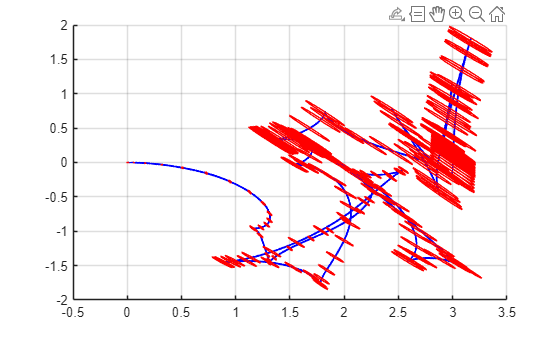

% Plot Ellipses (Metodo Analitico/Stachniss) ---

figure(2); clf; hold on; grid on;
plot(x, y, 'LineWidth', 1.5, "Color", "b");

% Custom function
plot_covariance_ellipses(x, y, Eps_x, 200, 30)